tic
data = readtable('data/data1/CHID46.csv');
data = table2array(data);
toc

Elapsed time is 0.026363 seconds.


data =    13.0000    4.8114
   16.0000    4.8116
   20.0000    4.8120
   23.0000    4.8113
   27.0000    4.8115
   30.0000    4.8113
   36.0000    4.8111
   38.0000    4.8111
   43.0000    4.8111


h = 0.01;
time = 0:h:80; 
init = [10^4 0 10^-3];
tau = 7;
c = 23;

x0 = [2.0187*(10^-7),1.2535*(10^-7),1.42261,1.56561,42.77631622*(10^3),0.03931];


ans = 0.0045

rng('default') % For reproducibility bootstrap


N=500;
params = zeros(N,6);

% options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
options = optimset('TolX',1e-7);


for m=1:N
    
    rep_data = data; 
    rep_data(:,2) = bootstrp(size(data,1),@mean,data(:,2));
    
    JJ = @(param) J(param, rep_data, h,time,init,tau,c);
    x = fminsearch(JJ,x0,options);
    params(m,:) = x;
end 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.062882 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.017575 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.022226 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.084085 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.016849 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.046589 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 


disp('finish');


ub = mean(params)+std(params)*1.645;
lb = mean(params)-std(params)*1.645;

ub(1,1)

ans = 8.9207e-07

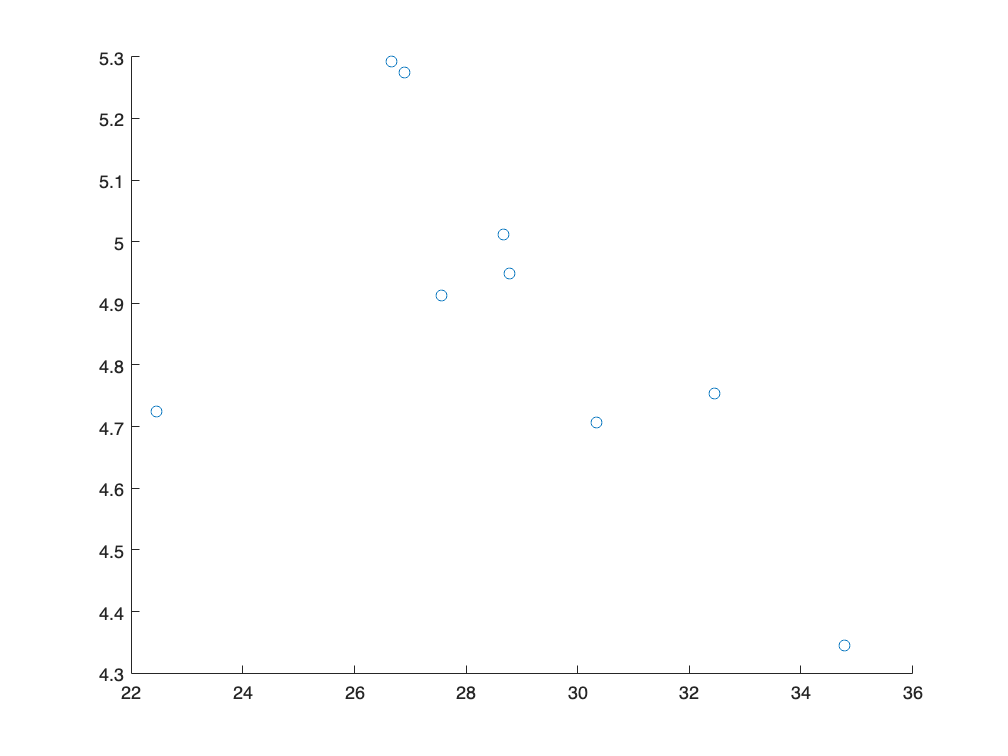



scatter(bootstat(:,1),bootstat(:,2))

function out=beta(t,tau,k,beta_0,beta_ifty)
    if t <= tau
        out = beta_0;
    else
        out = beta_ifty+(beta_0-beta_ifty)*exp(-k*(t-tau));
    end
end


function out = pred_logV(param, time, init, tau,c)
    beta_0=param(1);
    beta_ifty=param(2);
    k = param(3);
    dlt = param(4);
    p = param(5);
    d = param(6);
    
    f = @(t,x) [d*(10^4-x(1))-beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3);...
            beta(t,tau,k,beta_0,beta_ifty)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-c*x(3) ];
  
    [t,xa] = ode45(f,time,init);
    out = log10(xa(:,3));
    
end


function out=J(param,data,h,time,init,tau,c)
    pred = pred_logV(param, time, init, tau,c);

    num = size(data,1);
    sum = 0;
    for i = 1:num
        day = data(i,1);
        pred_logv = pred(day/h+1);
        
        sum = sum + (pred_logv - data(i,2))^2;
    end 
    
   out = sum/num;
end 

